# Binary Phase Shift Keying (PSK)

% Author Name : Atmanand Manoj Gauns
% Affiliation : Roll No.: 201104012
%               Branch : E&TC GCE
%               Year : TE Sem- 5 2021-22 

## Variables

clc;
clear;
fc=2;
fs=100*fc;
t=[0:1/fs:20];
A=5;

## Message Signal

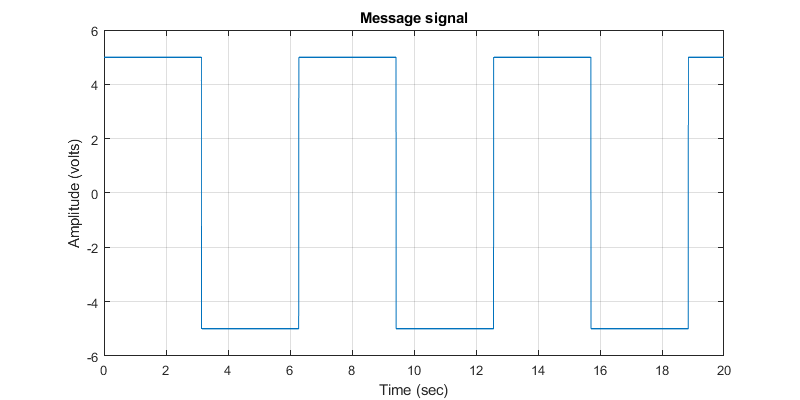

Vm=A.*square(t);
f1=figure;
plot(t,Vm);
xlabel('Time (sec)');
ylabel('Amplitude (volts)');
title('Message signal');
ylim([-6.00 6.00])
set(f1,'Position',[0 0 800 400]);
grid on;

## Carrier Signal

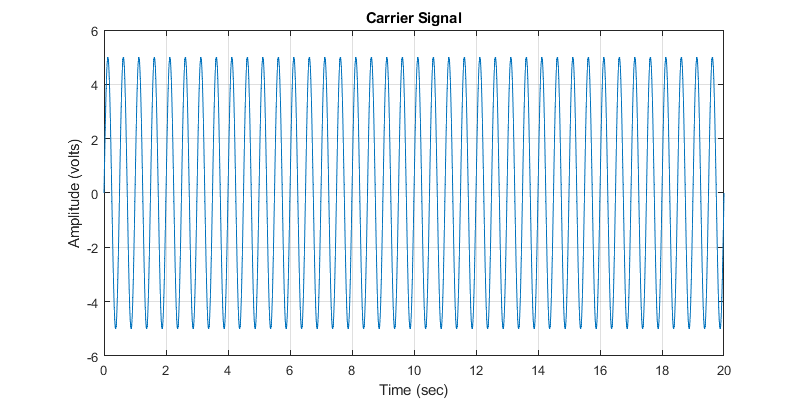

Vc=A.*sin(2.*pi.*fc.*t);
plot(t,Vc);
xlabel('Time (sec)');
ylabel('Amplitude (volts)');
title('Carrier Signal');
ylim([-6.00 6.00])
set(f1,'Position',[0 0 800 400]);
grid on;

## PSK Signal

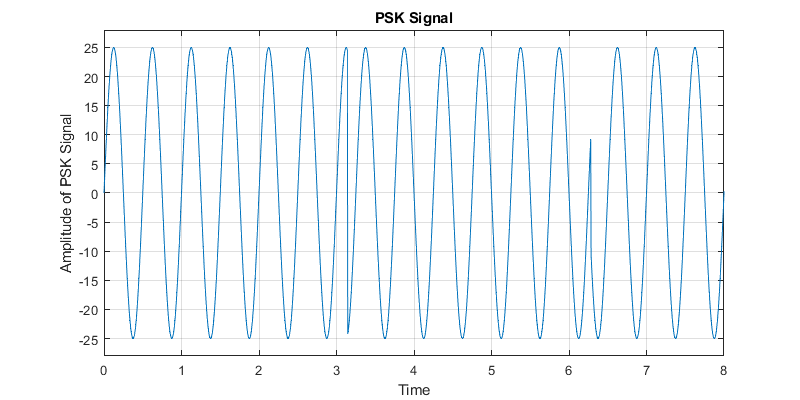

Vp=Vm.*Vc;
plot(t,Vp);
xlabel("Time");
ylabel("Amplitude of PSK Signal");
title('PSK Signal');

set(f1,'Position',[0 0 800 400]);
grid on;
xlim([0 8])
ylim([-28 28])

## Frequency Spectrum of PSK Signal

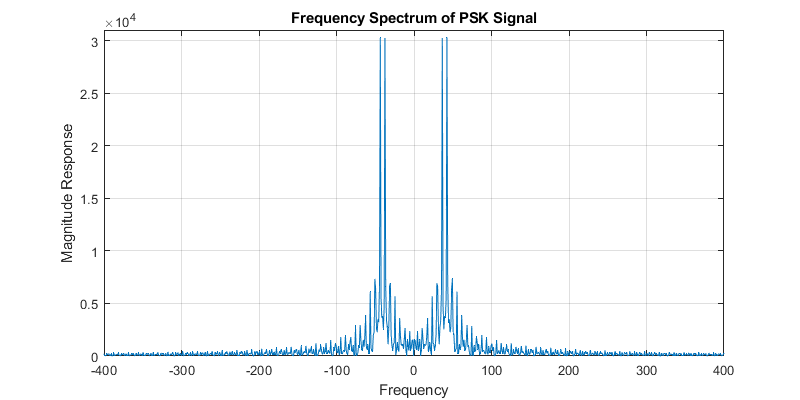

l=length(t);
i=(-l/2:1:l/2-1);
plot(i,(fftshift(abs(fft(Vp)))));
xlabel("Frequency");
ylabel("Magnitude Response");
title('Frequency Spectrum of PSK Signal');
set(f1,'Position',[0 0 800 400]);
grid on;

xlim([-400 400])
ylim([0 31000])